# Analysis of Simulations

## Trajectorie

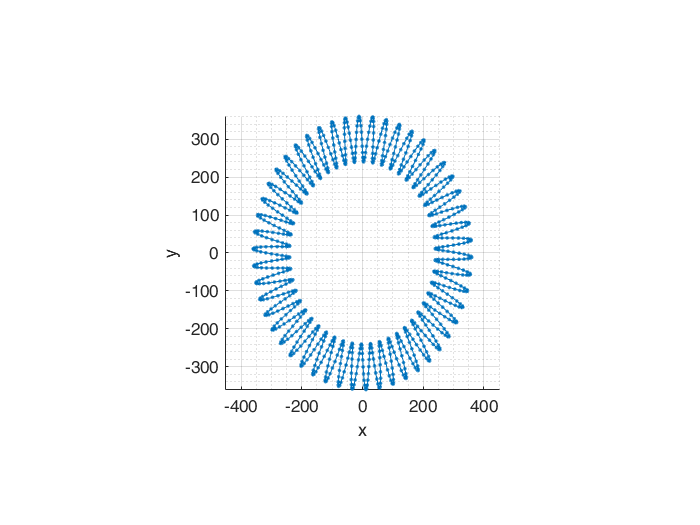

ax = axes();
plot3(ax,anaR.anaCord(:,1),anaR.anaCord(:,2),anaR.anaCord(:,3),'Marker','.','LineStyle','-')
xlabel('x');ylabel('y');zlabel('z')
grid on; grid minor;
axis vis3d; view([0 90]);rotate3d on;

## Vergleich Berechnung und Simulation

ticks = struct();
ticks.range = 0:pi/2:2*pi;
ticks.chars = {'0','pi/2','pi','3*pi/2','2*pi'};

### Vergleich der einzelnen Achsen

anaR.d = anaR.anaCord - anaR.simCord;
anaR.dist = vecnorm(anaR.d,2,2);        % euclidische norm: p=2

#### absolute Entfernung der Punkte

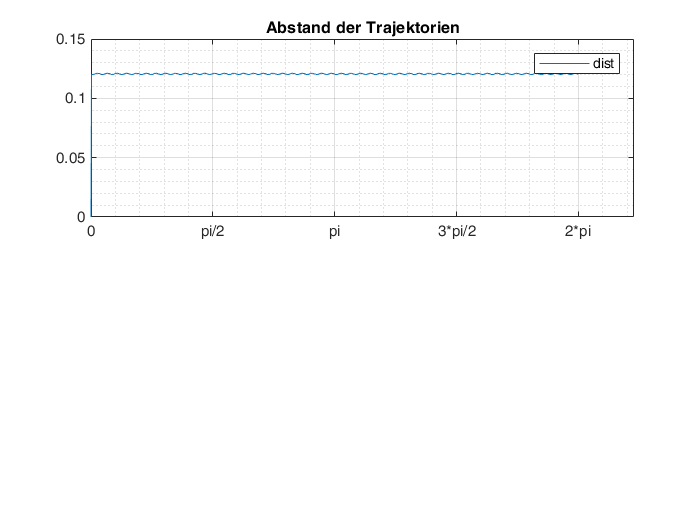

tH = tiledlayout(2,1);
ax(1) = nexttile(tH, 1);
plot(ax(1),anaR.angC,anaR.dist);
legend(ax(1),'dist');
title(ax(1),'Abstand der Trajektorien');

setupPlot(ticks);
tH = tiledlayout(3,1);

#### x-Achse

tH.Title.String = 'x Komponente der Trajektorienkoordinaten'

tH =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 1]
            Padding: 'normal'
        TileSpacing: 'normal'

  Show all properties


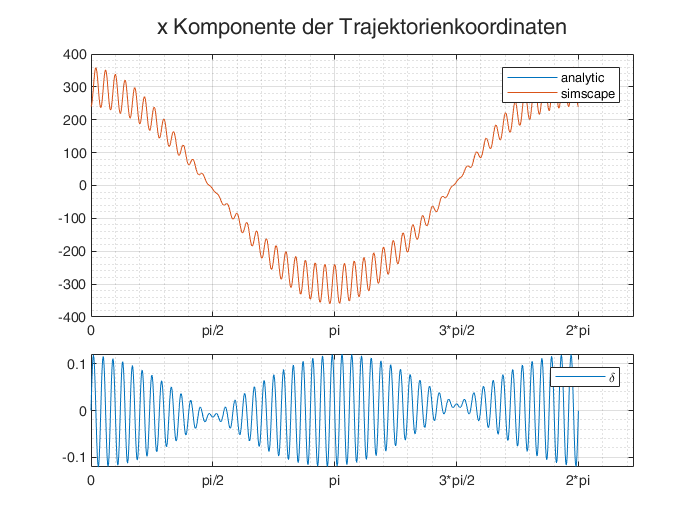

ax(1) = nexttile(tH, 1,[2 1]);
plot(anaR.angC,[anaR.anaCord(:,1), anaR.simCord(:,1)])
setupPlot(ticks); legend('analytic','simscape');

ax(2) = nexttile(tH,3);

[dxmaxval,dxmaxloc] = findpeaks(anaR.d(:,1),anaR.angC,'MinPeakProminence',4);
mH = plot(anaR.angC,anaR.d(:,1));
if abs(dxmaxval)>1e-3
    line(dxmaxloc,dxmaxval,'Marker','|','LineStyle','none','Color','red');
    datatip(mH,dxmaxloc,dxmaxval);
end
setupPlot(ticks); legend('\delta');
linkaxes(ax,'x')

#### y-Achse

tH = tiledlayout(3,1);
tH.Title.String = 'y Komponente der Trajektorienkoordinaten'

tH =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 1]
            Padding: 'normal'
        TileSpacing: 'normal'

  Show all properties


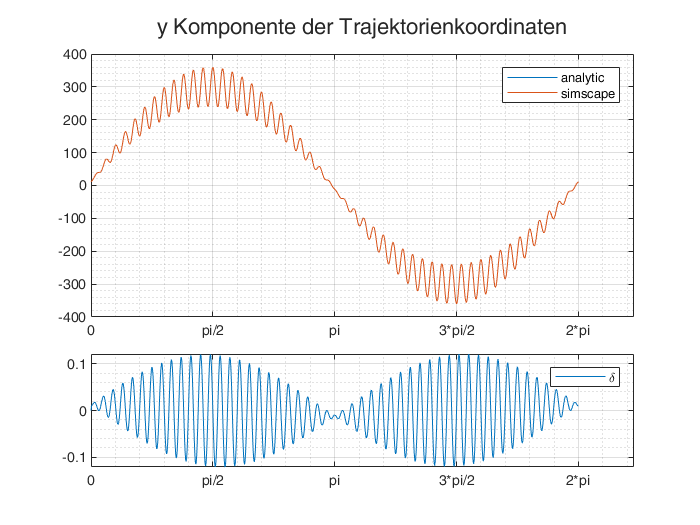

ax(1) = nexttile(tH,1,[2 1]);
plot(anaR.angC,[anaR.anaCord(:,2), anaR.simCord(:,2)])
setupPlot(ticks); legend('analytic','simscape');

ax(2) = nexttile(tH,3);

[dymaxval,dymaxloc] = findpeaks(anaR.d(:,2),anaR.angC,'MinPeakProminence',4);
[dyminval,dyminloc] = findpeaks(-anaR.d(:,2),anaR.angC,'MinPeakProminence',4);
mH = plot(anaR.angC,anaR.d(:,2));
if abs(mean([dymaxval,dyminval])) > 1e-3
    line(dymaxloc,dymaxval,'Marker','|','LineStyle','none','Color','red');
    line(dyminloc,-dyminval,'Marker','|','LineStyle','none','Color','green');
    datatip(mH,dymaxloc,dymaxval);
    datatip(mH,dyminloc,-dyminval);
end
setupPlot(ticks); legend('\delta');
linkaxes(ax,'x')

#### z-Achse

tH = tiledlayout(3,1);
tH.Title.String = 'z Komponente der Trajektorienkoordinaten'

tH =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 1]
            Padding: 'normal'
        TileSpacing: 'normal'

  Show all properties


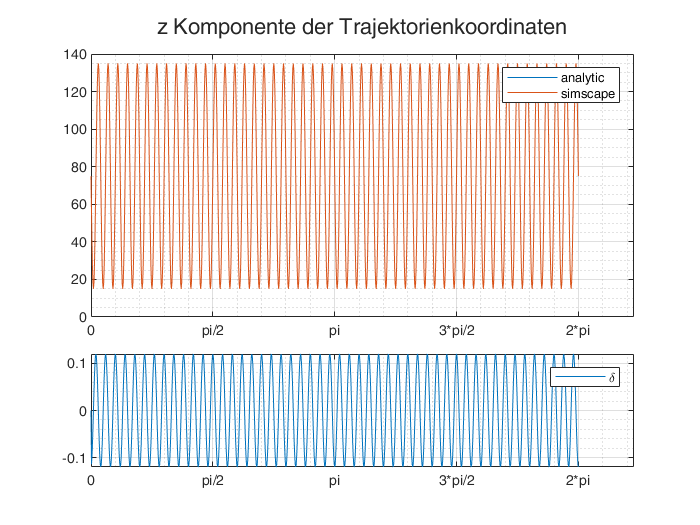

ax(1) = nexttile(tH,1,[2 1]);
plot(anaR.angC,[anaR.anaCord(:,3), anaR.simCord(:,3)])
setupPlot(ticks); legend('analytic','simscape');

ax(2) = nexttile(tH,3);

plot(anaR.angC,anaR.d(:,3))
setupPlot(ticks); legend('\delta');
linkaxes(ax,'x')

### Gesamt

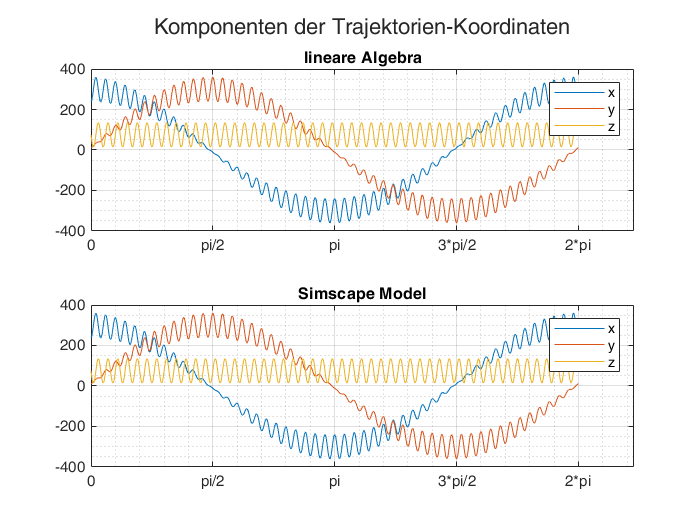

ltxt = {'x','y','z'};
tH = tiledlayout(2,1);
tH.Title.String = 'Komponenten der Trajektorien-Koordinaten';
ax(1) = nexttile(tH,1);
plot(anaR.angC,anaR.anaCord);
setupPlot(ticks);
legend(ax(1),ltxt);
title(ax(1),'lineare Algebra');
ax(2) = nexttile(tH,2);
plot(anaR.angC,anaR.simCord)
setupPlot(ticks);
legend(ax(2),ltxt);
title(ax(2),'Simscape Model');
linkaxes(ax,'x')

#### Postprocessing

save simulation data to file

s = struct('simR',simR,'anaR',anaR); % save struct
save('D:\git\ba\simRes','-struct','s');

clearvars d*max* dymin* mH ax ticks s

function setupPlot(ticks)
set(gca,'XTick',ticks.range)
set(gca,'XTickLabel',ticks.chars)

grid on;
grid minor;
end